**Image Adjustment Notebook**

**Kuan-Min Lee**

**Relative MATLAB Function:**

**imadjust(I,[low_in high_in], [low_out high_out], gamma);**

**Basic Theory Explanation:**

It maps intensity values in I to **new values, where gama function specifies the shape of the curve** d**escribing relationship between I and the new value:**

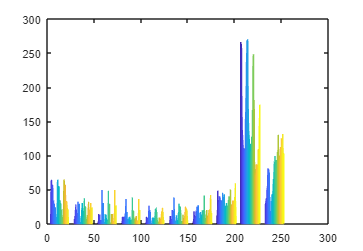

car_img=imread("car.jpg"); % read in sample image
figure(1);
hist(double(car_img))

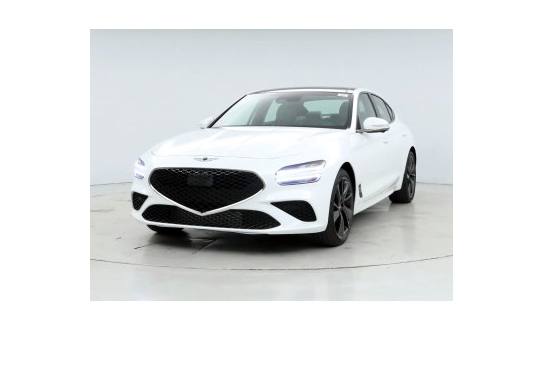

figure(2)
imshow(car_img)

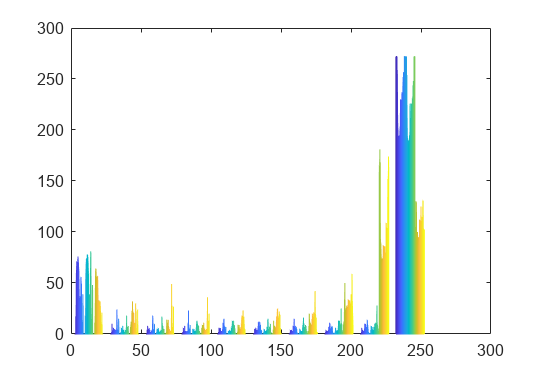

car_img_new=imadjust(car_img,[.2 .3 0; .6 .7 1],[]);
figure(3)
hist(double(car_img_new))

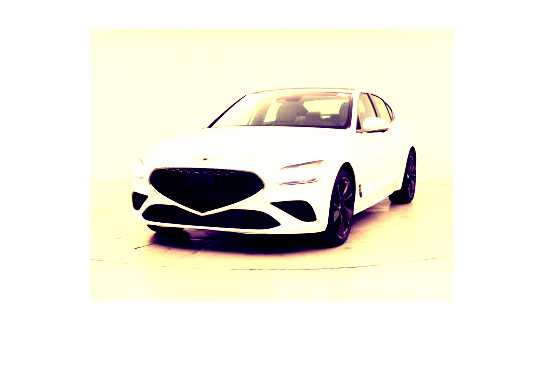

figure(4)
imshow(car_img_new)

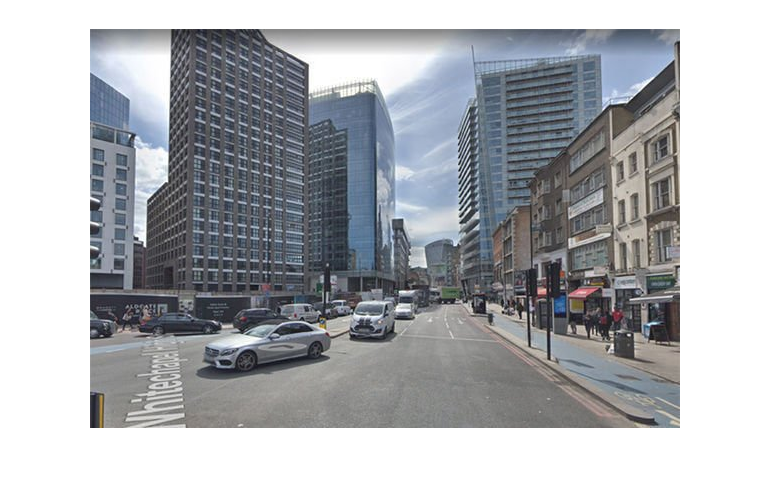

map_img=imread("google-maps-how-to-get-street-view-google-maps-2421144.jpg");
map_img_new=imadjust(map_img,[.2 .3 0; .6 .7 1],[]);
figure(5)
imshow(map_img)

figure(6)
hist(double(map_img))

Error using  .* 
Integers can only be combined with integers of the same class, or scalar doubles.

Error in linspace (line 46)
        y = d1 + (0:n1).*(d2 - d1)./n1;

Error in hist (line 123)
        edges = linspace(miny,maxy,x+1);

figure(7)
imshow(map_img_new)
figure(8)
hist(double(map_img_new))